# PRACTICA 7. SERVICIOS TELEMATICOS MULTIMEDIA

% Guillermo Aldrey Pastor

% Fecha de Entrega: 28/12/2020
 
clc;clear all;close all;

## PARTE A

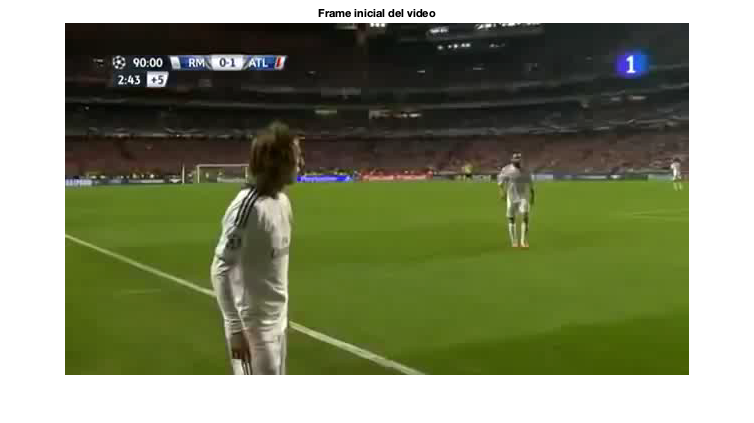

% Lo primero que tenemos que hacer es preparar el video en matlab
% utilizando "prueba_leer_video.m"
    
    load('gol.mat');

% Una vez hemos convertido nuestro video al formato soportado por matlab, 
% mostramos tanto el frame inicial como el final del mismo

    figure;
    imshow(mov(1).cdata);
    title('Frame inicial del video');

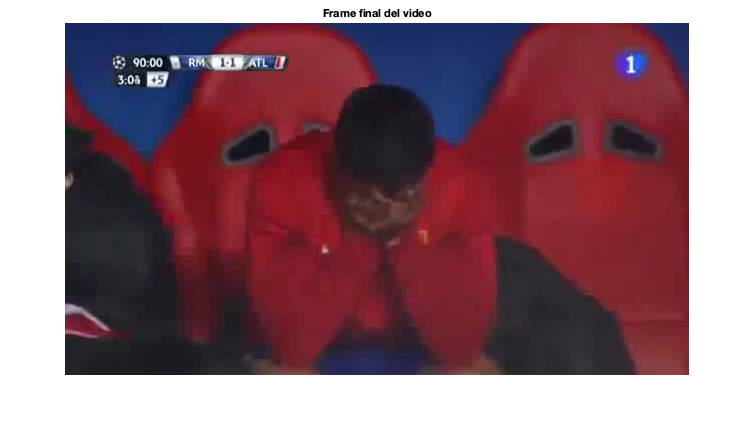


    figure;
    imshow(mov(length(mov)).cdata);
    title('Frame final del video');

    
% El siguiente paso es usar el codigo "mpegproj" y adaptarlo a nuestro
% video. Desde aqui ya podemos realizar los siguientes puntos de esta parte
% de la practica.

   


MPEG Project
20 frames


Encode time: 9 sec
Decode time: 2 sec


    load('lastmov.mat');
    
    % Identificar y mostrar un frame I
    
    disp(mpeg{1,1}(1,1));

     type: 'I'
      mvx: 0
      mvy: 0
    scale: [31 31 31 31 31 31]
     coef: [8×8×6 double]



      
    % Identificar y mostrar lo que contiene un frame P
    
    disp(mpeg{1,2}(1,1));

     type: 'P'
      mvx: 0
      mvy: 0
    scale: [31 31 31 31 31 31]
     coef: [8×8×6 double]



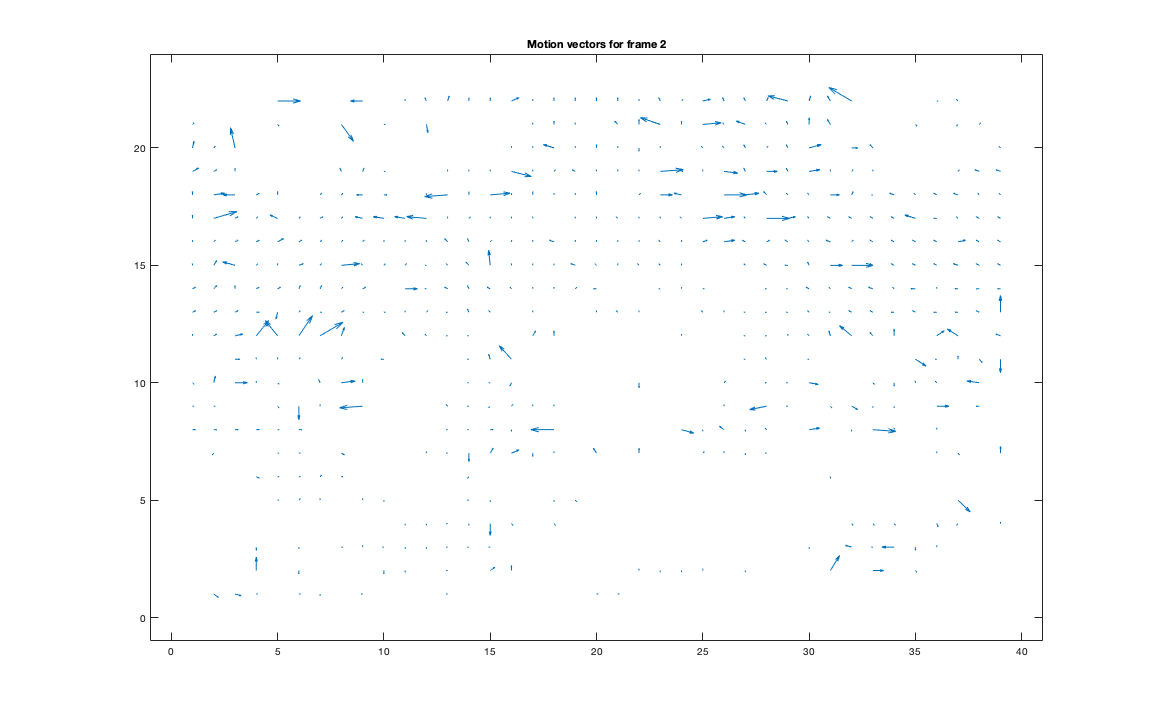

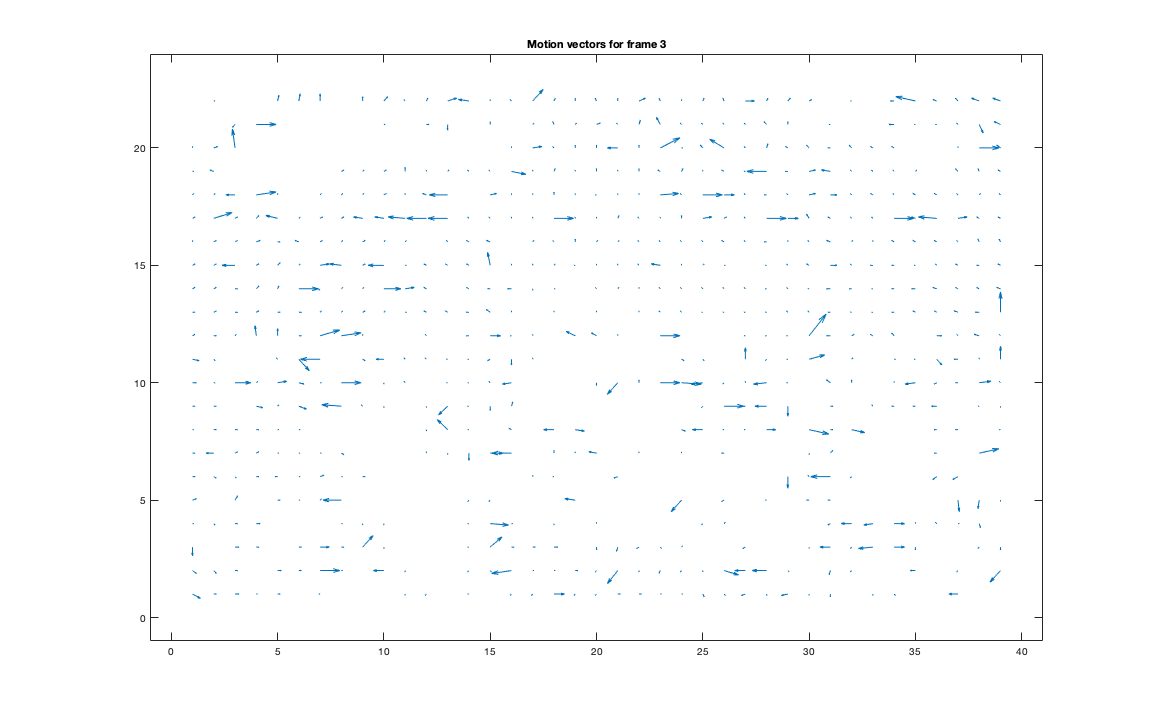

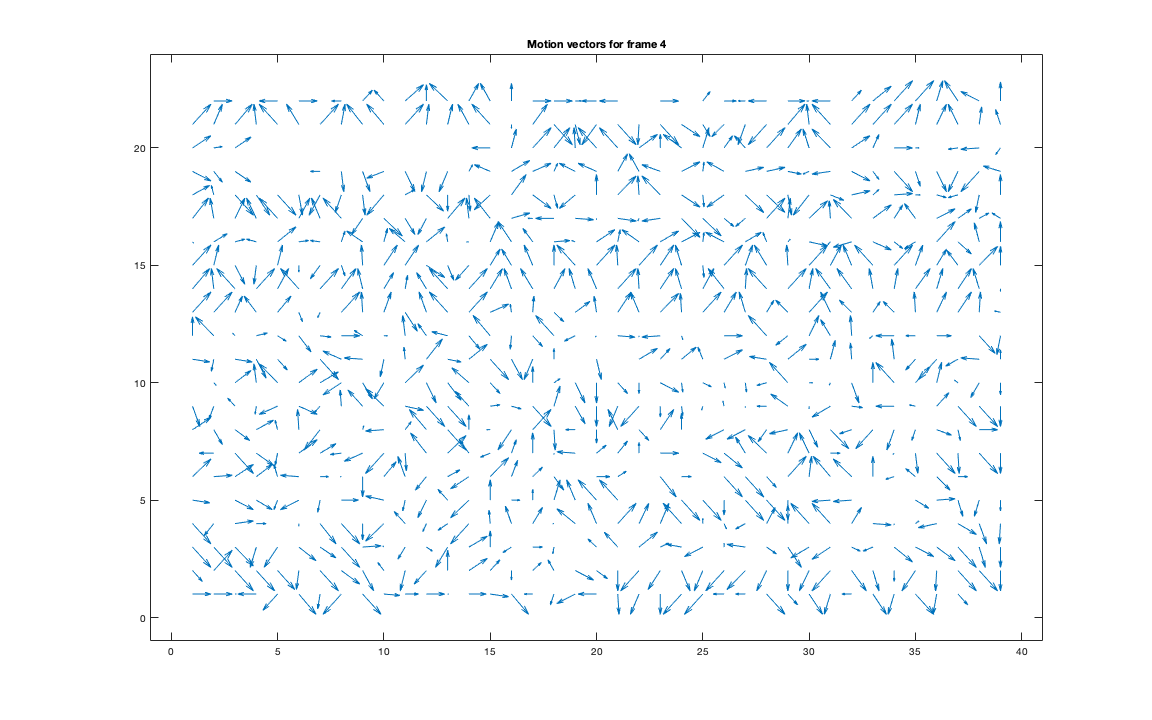

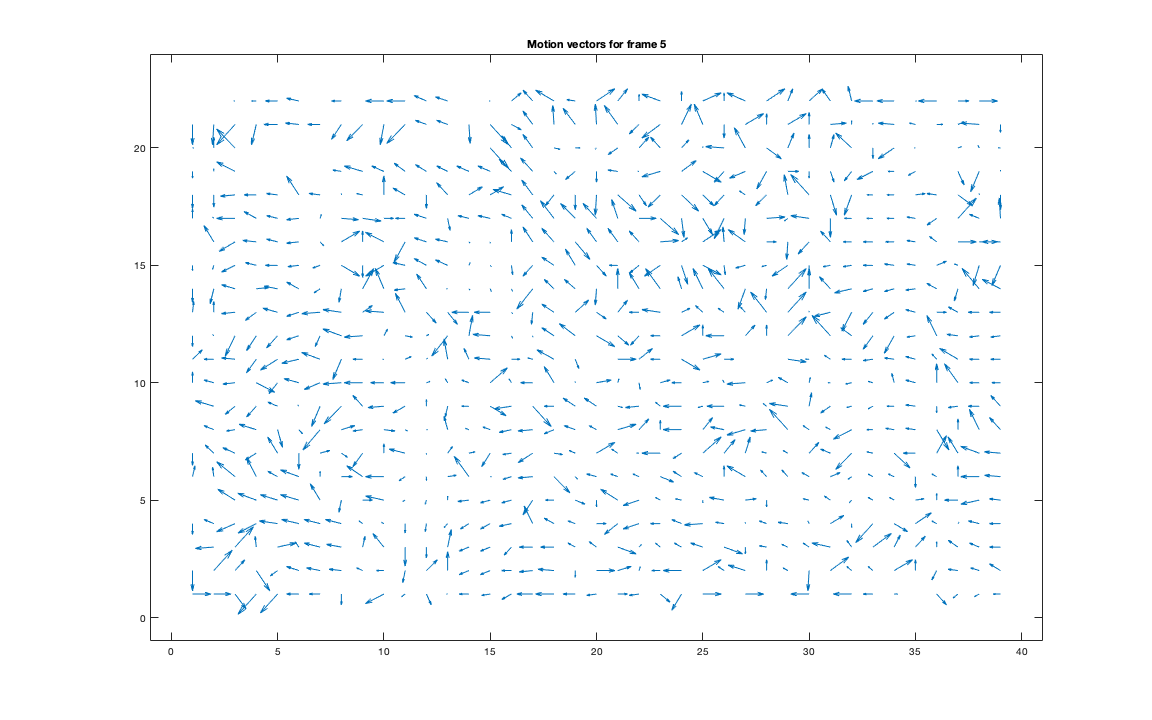

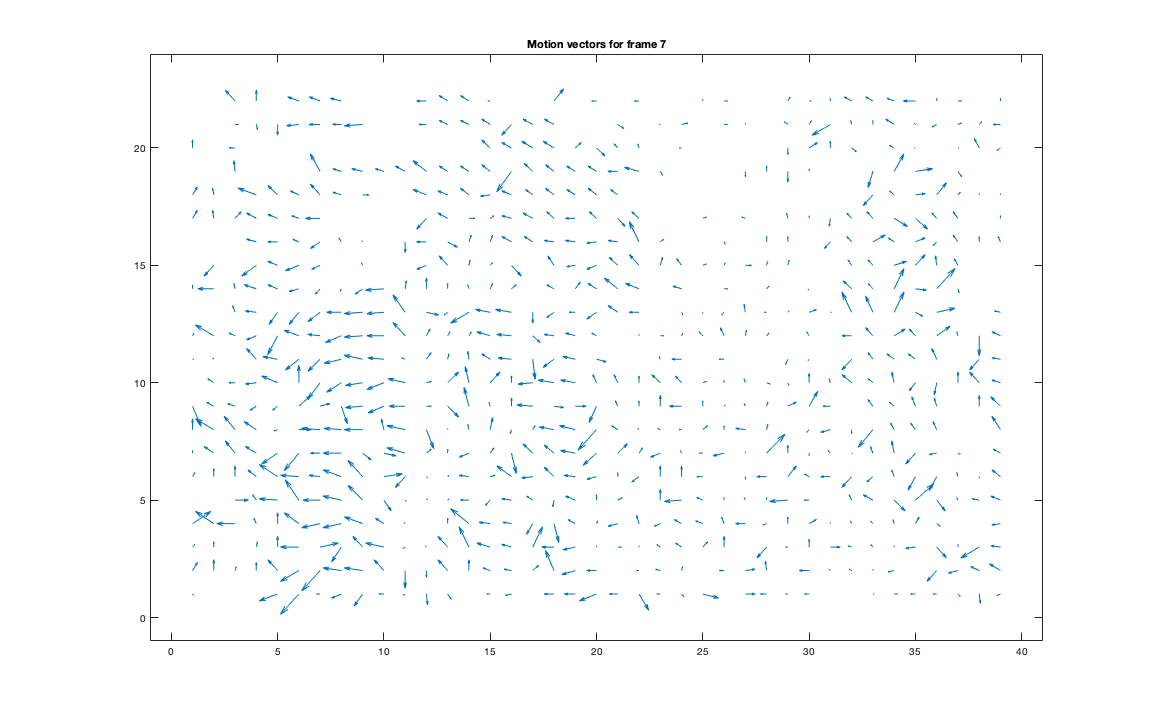

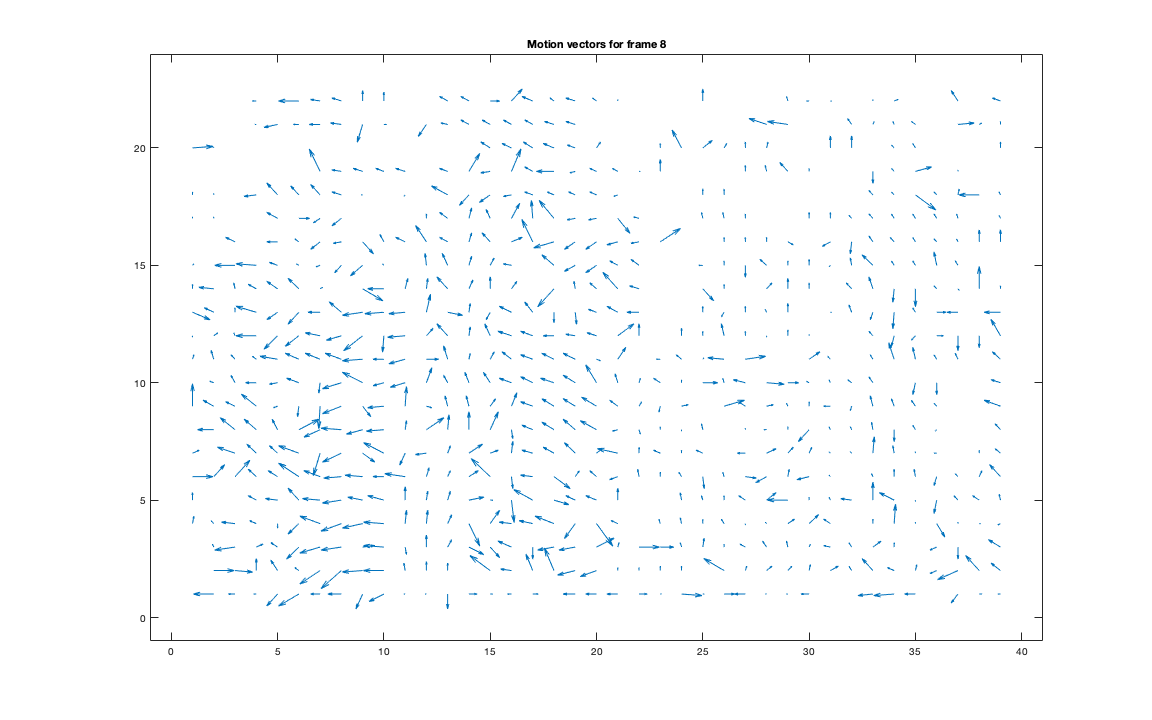

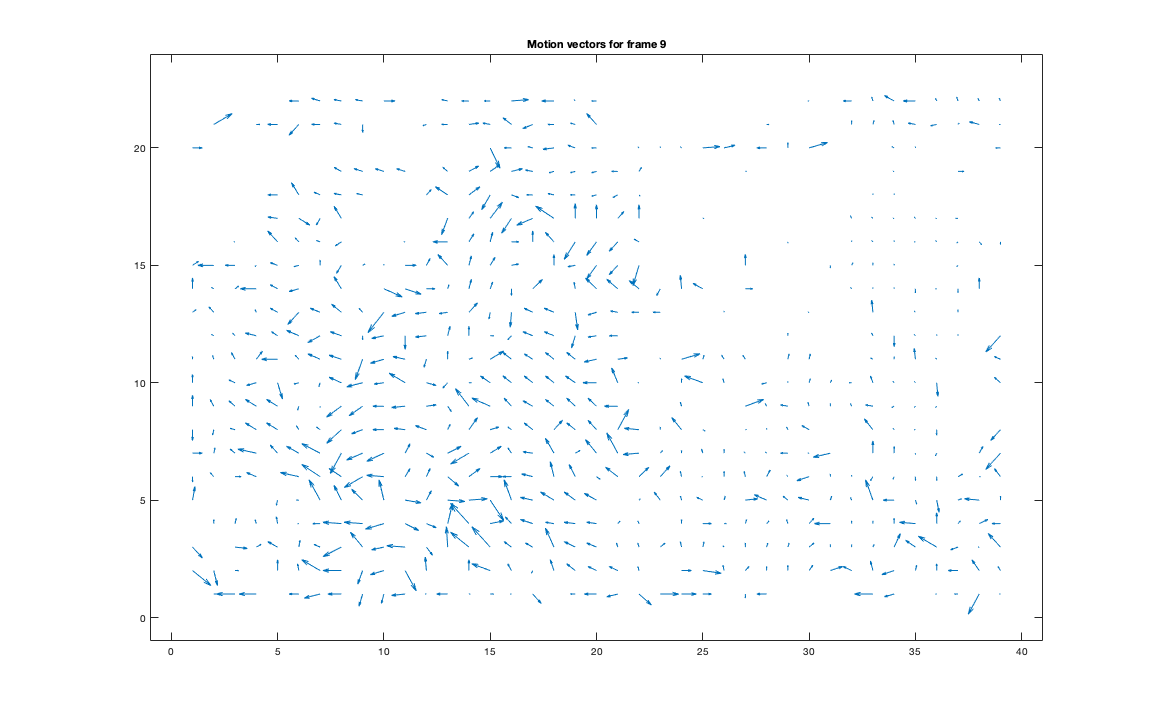

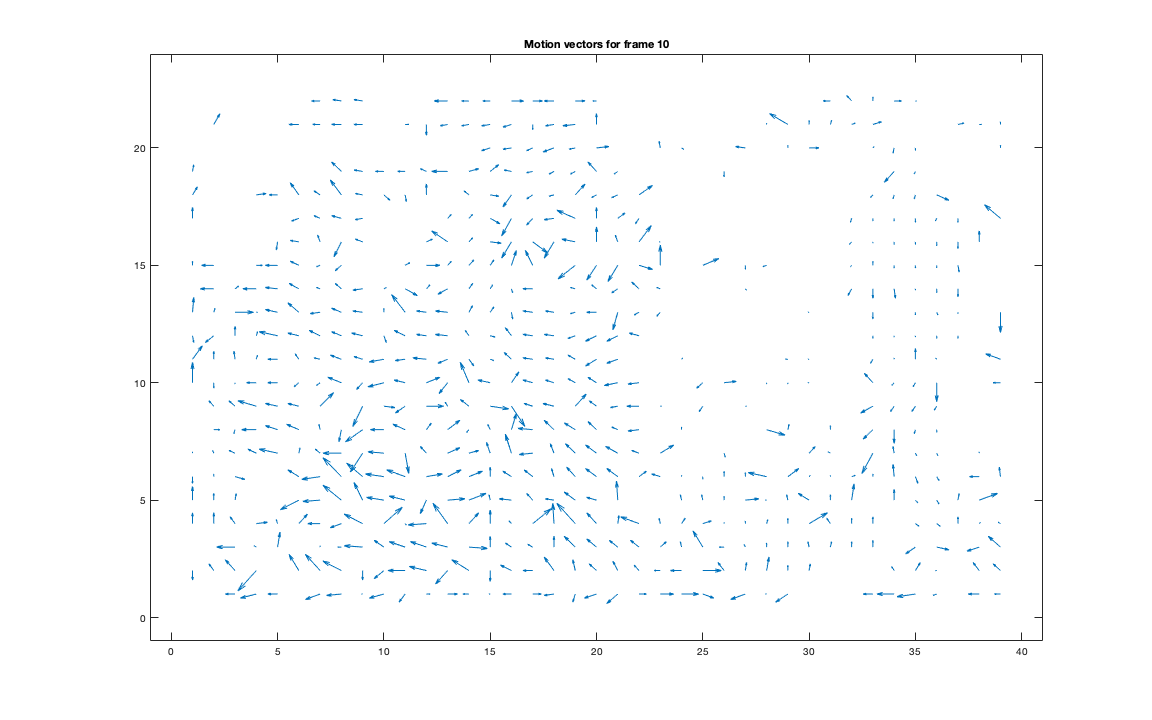

    
    % Mostrar una secuencia cualquiera de al menos tres frames con sus vectores de movimiento
    
    quiverplot;

    
    % Mostrar las características del video codificado
    
    whos mpeg;

  Name      Size               Bytes  Class    Attributes

  mpeg      1x20            63466320  cell               



   
    % Mostrar las características del video decodificado
    
    whos mov2;

  Name        Size                     Bytes  Class    Attributes

  mov2      352x624x3x20            13178880  uint8              



    
    % Evaluar la relación señal ruido
    
    energia = 0;
    
    for i=1:20 % 20 frames
        energia = energia+sum(mov(:,:,:,i).^2);
    end
    
    energia = sum(sum(energia));
    
    ruido = 0;
    
    for i=1:20 % 20 frames
        ruido = ruido+sum((mov2(:,:,:,i)-mov(:,:,:,i)).^2);
    end
    
    ruido = sum(sum(ruido));
    SNR = energia/ruido;
    
    disp(SNR);

   12.2914



## PARTE B

% Vamos a volver a usar el video que utilizamos en la parte A.

% Comenzamos utilizando el codigo que nos dan "hace_mpeg" y lo adaptamos a
% nuestro video. Esto convertira el video a formato mp4.Al igual que antes, 
% a partir de aqui podemos resolver el resto de apartados.

    % Identificar y mostrar un frame I
    
    % disp(I1(1:8,1:8));
    
    % Identificar y mostrar lo que contiene un frame P
    
    % disp(B2(1:8,1:8));
    
    % Identificar y mostrar lo que contiene un frame B
    
    % disp(P4(1:8,1:8));
    
    % Comentar cómo se ha construido el frame I (dar detalles)
    
    % Los frames de tipo I que se construyen como una imagen independiente. 
    % No se produce codificación temporal ni tampoco aparecen en ellos
    % vectores movimiento. Este tipo de frames son codificados
    % independientemente de otros y permiten el acceso aleatorio y la 
    % edición de video.
    
    % Comentar cómo se ha construido el frame P (dar detalles)
    
    % Los frames de tipo P que se ha codificado como la diferencia 
    % entre el frame P actual el frame previo I. Para procesar este frame, 
    % se contempla el movimiento compensado hacia adelante de frames
    % previos tipo I o P. Se codifica el error de predicción y solo un
    % vector de movimiento.
    
    % Comentar cómo se ha construido el frame B (dar detalles)
    
    % Los frames de tipo B son frames de predicción bidireccional que 
    % alcanzan la mejor compresión. En este caso, el movimiento se ha 
    % compensado hacia adelante y hacia atrás, interpolando el frame 
    % previo I y el posterior P. Se codifica el error de predicción y 
    % hasta dos vectores de movimiento.

    % Mostrar las características del video codificado
   
    gol_mp4 = importdata('gol.mp4');
    whos gol_mp4;

  Name           Size                       Bytes  Class    Attributes

  gol_mp4      360x630x3x516            351086400  uint8              



    % Evaluar la relación de compresión

## PARTE C

## CONCLUSIONES GENERALES